A=[1 2 3; 5 9 8; 5 5 -20];

r = 2

M = 3

N = 3

Not independent row


Not independent column


B =      1     5     5
     2     9     5
     3     8   -20


ans = 2

m = 3

n = 3

r = 3

M = 3

N = 3

Row independent


Column independent


M =      4     1     0     6
    -2     2     1    -1
     0    -1     2    -8
    -2     3     4    -8


Matrices are dependent


Matrices are independent


M =      0     0    -1
     1     1     1
     0     1     1


ans = 3

Polynomials are linearly independent


$$w = -1$$

Linearly independent functions


$$M = \left(\begin{array}{ccc} \sin\left(x\right) & \cos\left(x\right) & \sin\left(x+1\right) \end{array}\right)$$

$$w = 0$$

functions are dependent


No form basis


Forms basis


r=rank(A)
[M,N]=size(A)
if(M==r)
    disp("Independent row")
else
    disp("Not independent row")
end
if(N==r)
    disp("Independent column")
else
    disp("Not independent column")
end

B=A'
rank(B)
[m,n]=size(B)

A=[1 2 -5; -1 0 1; 1 1 -1];
r=rank(A)
[M,N]=size(A)
if(M==r)
disp("Row independent")
else
    disp("Row dependent")
end
if(N==r)
    disp("Column independent")
else
    disp("column dependent")
end

A=[4 0; -2 -2];
B=[1 -1; 2 3];
C=[0 2; 1 4];
D=[6 -8; -1 -8];
M=[A(:),B(:),C(:),D(:)]
if(rank(M)==size(M,2))
    disp("Matrices are independent");
else
    disp("Matrices are dependent");
end
A=[3 6; 3 -6];
B=[0 -1; -1 0];
C=[0 -8; -12 -4];
D=[1 0; -1 2];
M=[A(:),B(:),C(:),D(:)];
if(rank(M)==size(M,2))
    disp("Matrices are independent");
else
    disp("Matrices are dependent");
end

P1=[0 ;1 ;0];
P2=[0 ;1 ;1];
P3=[-1 ;1 ;1];
M=[P1(:),P2(:),P3(:)]
rank(M)
if(rank(M)==size(M,2))
    disp("Polynomials are linearly independent");
else
    disp("Polynomials are dependent");
end

syms x;
f1=sin(x);
f2=cos(x);
M=[f1 f2];
W=det([M;diff(M,x)]);
w=simplify(W)
if(w~=0)
    disp("Linearly independent functions");
else
    disp("Linearly dependent functions");
end
syms x;
f1=sin(x);
f2=cos(x);
f3=sin(1+x);
M=[f1 f2 f3]
W=det([M;diff(M,x);diff(M,x,2)]);
w=simplify(W)
if(w~=0)
    disp("Functions are independent")
else 
    disp("functions are dependent")
end

a=[1;1;1];
b=[2;-1;-1];
c=[-1;2;3];
d=[-2;1;1];
M=[a b c d];
if(rank(M)==size(M,2))
    disp("forms basis")
else
    disp("No form basis")
end

syms x;
a=sin(x);
b=cos(x);
c=tan(x);
M=[a b c];
w=det([M;diff(M,x);diff(M,x,2)]);
W=simplify(w);
if(W~=sym(0))
    disp("Forms basis")
else
    disp("No form basis")
end

A=randi([0,9],5,4)*randi([0,9],4,5)

A =    108   144    60   104    52
    95   113    57    82    52
    86   134    58    92    52
    79   109    48    78    46
    90   108    74    73    73


rank(A)

ans = 4

n=A(3,5)

n = 52

b=A(1,:)

b =    108   144    60   104    52


c=A([1 3],:)

c =    108   144    60   104    52
    86   134    58    92    52


b=A(:,2)

b =    144
   113
   134
   109
   108


c=A(:,[2 4])

c =    144   104
   113    82
   134    92
   109    78
   108    73


A=[1 2 3; 5 9 8; 5 5 -20]

A =      1     2     3
     5     9     8
     5     5   -20


[RR,ic]=rref(A)

RR =      1     0   -11
     0     1     7
     0     0     0


ic =      1     2


rowspacebasis=RR(ic,:)

rowspacebasis =      1     0   -11
     0     1     7


c=A'

c =      1     5     5
     2     9     5
     3     8   -20


columnspacebasis=A(:,ic)

columnspacebasis =      1     2
     5     9
     5     5


n=null(A,'r')

n =     11
    -7
     1


A=[1 -1 2 3; 0 2 1 4; 1 1 3 1; 2 0 5 4]

A =      1    -1     2     3
     0     2     1     4
     1     1     3     1
     2     0     5     4


v=[5;1;-2;0]

v =      5
     1
    -2
     0


w=[0;2;2;2]

w =      0
     2
     2
     2


u=[-1;2;-1;1]

u =     -1
     2
    -1
     1


m=[3;-1;7;7]

m =      3
    -1
     7
     7


[A w]

ans =      1    -1     2     3     0
     0     2     1     4     2
     1     1     3     1     2
     2     0     5     4     2


[A;w']

ans =      1    -1     2     3
     0     2     1     4
     1     1     3     1
     2     0     5     4
     0     2     2     2


A*w 

ans =      8
    14
    10
    18


w'*A

ans =      6     6    18    18


if(rank(A)==rank([A w]))
    disp("Column space")
elseif(rank(A)==rank([A;w']))
    disp("Row space")
elseif norm(A*w)<1e-10
    disp("Null space")
elseif norm(w'*A)<1e-10
    disp("Left null space")
else
    disp("Nothing")
end

Column space


A = [1 2 3;2 4 6;1 1 1]

A =      1     2     3
     2     4     6
     1     1     1


[R,pc]=rref(A)

R =      1     0    -1
     0     1     2
     0     0     0


pc =      1     2


r=length(pc)

r = 2

Row=R(pc,:)

Row =      1     0    -1
     0     1     2


Column=A(:,pc)

Column =      1     2
     2     4
     1     1


R=[1 0 1 0; 0 1 1 0; 0 0 0 1]

R =      1     0     1     0
     0     1     1     0
     0     0     0     1


A=randi([0,9],4,3)*R

A =      2     4     6     6
     4     9    13     5
     5     3     8     6
     9     7    16     6


rref(A)

ans =      1     0     1     0
     0     1     1     0
     0     0     0     1
     0     0     0     0


A=randi([0,9],9,3)*randi([0,9],3,9)

A =     96    66    66    36    48    72   102   102    72
    93    53    67    27    64    40    94    73    68
    17     6     8     9    14    10    23    29    32
    69    48    42    33    30    66    81    99    72
   124    79    87    42    72    76   129   117    92
    91    69    59    41    34    90   102   120    76
   107    71    69    45    54    86   120   132   100
   125    84    90    41    68    80   127   112    80
   114    79    87    32    62    66   109    82    52


[RR,pc]=rref(A)

RR =     1.0000         0         0    1.0000    1.0000    1.0000    2.0000    3.5000    4.0000
         0    1.0000         0    0.3636   -1.4091    2.0455    0.0455    1.0682   -0.9091
         0         0    1.0000   -1.2727    0.6818   -2.4091   -1.4091   -4.6136   -3.8182
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


pc =      1     2     3


rbasis=RR(pc,:)

rbasis =     1.0000         0         0    1.0000    1.0000    1.0000    2.0000    3.5000    4.0000
         0    1.0000         0    0.3636   -1.4091    2.0455    0.0455    1.0682   -0.9091
         0         0    1.0000   -1.2727    0.6818   -2.4091   -1.4091   -4.6136   -3.8182


cbasis=A(:,pc)

cbasis =     96    66    66
    93    53    67
    17     6     8
    69    48    42
   124    79    87
    91    69    59
   107    71    69
   125    84    90
   114    79    87


nullspc=null(A,'r')

nullspc =    -1.0000   -1.0000   -1.0000   -2.0000   -3.5000   -4.0000
   -0.3636    1.4091   -2.0455   -0.0455   -1.0682    0.9091
    1.2727   -0.6818    2.4091    1.4091    4.6136    3.8182
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


leftnspac=null(A','r')

leftnspac =    -1.0952   -0.7381   -1.6270   -1.2143   -0.9127   -0.6984
    0.5714   -0.5714    0.7619    0.2857   -0.5238   -0.8095
   -1.0000         0   -0.3333   -1.0000    0.6667    1.6667
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


rbasis*nullspc

ans =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



if (A==cbasis*rbasis)
    disp("CR decomposition; A=CR")
else
    disp("WTF am i doing and A!=CR")
end

WTF am i doing and A!=CR


a=A

a =     96    66    66    36    48    72   102   102    72
    93    53    67    27    64    40    94    73    68
    17     6     8     9    14    10    23    29    32
    69    48    42    33    30    66    81    99    72
   124    79    87    42    72    76   129   117    92
    91    69    59    41    34    90   102   120    76
   107    71    69    45    54    86   120   132   100
   125    84    90    41    68    80   127   112    80
   114    79    87    32    62    66   109    82    52


b=inv(A)-(1/det(A))*adj(A)

Unrecognized function or variable 'adj'.

A=randi([0,9],4,3)

A =      1     3     2
     2     6     3
     3     0     1
     4     4     5


if rank(A)==size(A,2)
    disp("Yes n=3")
else
    disp("Fuck off")
end

Yes n=3


ALI=inv(A'*A)*A'

ALI =    -0.0830    0.1337    0.4562   -0.1382
    0.0364    0.2770    0.0603   -0.1928
    0.0762   -0.3419   -0.4050    0.4556


if norm((ALI*A)-eye(size(A,2)))<1e-10
    disp("Yes ALI*A produces identity matrix")
else
    disp("What have you been fkin doing mate ?")
end

Yes ALI*A produces identity matrix


A=randi([0,9],5,7)

A =      4     5     3     8     1     7     6
     8     4     0     3     9     0     1
     5     0     3     0     3     9     5
     2     7     2     3     3     1     7
     5     5     2     7     2     2     9


if rank(A)==size(A,1)
    disp("Rank of A = m = 5")
else
    disp("WTF nigga")
end

Rank of A = m = 5


ARI=A'*inv(A*A')

ARI =    -0.0434    0.0467    0.0273   -0.0991    0.0984
    0.0778    0.0126   -0.0480    0.1588   -0.1443
    0.0166   -0.0142    0.0186    0.0376   -0.0342
    0.1045    0.0180   -0.0804   -0.0986    0.0443
   -0.0174    0.0642    0.0179    0.0480   -0.0542
    0.0913   -0.0118    0.0538    0.0147   -0.1060
   -0.1205   -0.0554    0.0540    0.0212    0.1454


if norm(A*ARI - eye(size(A,1)))<1e-10
    disp("A*ARI=I")
else
    disp("Fk off")
end

A*ARI=I


A=randi([0,9],9,9)

A =      9     9     3     0     1     1     1     3     1
     4     7     5     7     6     2     6     4     5
     2     5     2     9     6     9     2     6     8
     4     4     7     0     4     6     8     0     7
     1     2     3     5     1     7     8     1     1
     1     7     7     5     4     8     4     6     0
     2     0     9     6     5     0     3     2     6
     7     1     0     2     3     4     9     1     4
     6     7     4     6     8     7     0     0     4


if norm(inv(A)-pinv(A))<1e-10
    disp("inverse of a is equal to pseudo inverse of A")
else
    disp("inverse of a is not equal to pseudo inverse of A")
end

inverse of a is equal to pseudo inverse of A


A=randi([0,9],5,4)

A =      3     1     9     0
     3     0     0     8
     9     2     1     3
     4     5     4     6
     7     6     3     5


if norm(pinv(A)-(inv(A'*A)*A'))<1e-10
    disp("pseudo inverse is equal to left inverse of A")
else
    disp("Pseudo inverse of A is not equal to left inverse of A")
end

pseudo inverse is equal to left inverse of A


A=randi([0,9],3,7)

A =      0     2     8     7     6     0     2
     6     4     5     2     6     9     0
     3     6     0     8     3     6     2


if norm(pinv(A)-(A'*inv(A*A')))<1e-10
    disp("Pseudo inverse is equal to right inverse")
else
    disp("Pseudo inverse is not equal to right inverse")
end

Pseudo inverse is equal to right inverse


A=[3 1 -1; 1 2 0; 0 1 2; 1 1 -1]

A =      3     1    -1
     1     2     0
     0     1     2
     1     1    -1


v=[-3;-3;8;9]

v =     -3
    -3
     8
     9


if norm(rank(A)-size(A,2))<1e-10
    p1=A*inv(A'*A)*A'*v;
    disp(p1);
else
    p1=A*pinv(A)*v;
    disp(p1);
end

   -2.0000
    3.0000
    4.0000
   -0.0000





B=[1 1; 1 2; 0 1]

B =      1     1
     1     2
     0     1


u=[2;1;3]

u =      2
     1
     3


if norm(rank(B)-size(B,2))<1e-10
    p2=B*inv(B'*B)*B'*u;
    disp(p2)
else
    p2=B*pinv(B)*u;
    disp(p2);
end

    0.6667
    2.3333
    1.6667




C=[1 1 2 4; 1 2 3 6; 0 1 1 2]

C =      1     1     2     4
     1     2     3     6
     0     1     1     2


u=[2;1;3]

u =      2
     1
     3


if norm(rank(C)-size(C,2))<1e-10
    p3=C*inv(C'*C)*C'*u;
    disp(p3);
else
    p3=C*pinv(C)*u;
    disp(p3);
end

    0.6667
    2.3333
    1.6667



A=randi([0,9],9,9);
if norm(inv(A)-pinv(A))<1e-10
    disp("Yes")
else
    disp("No")
end

Yes


A=randi([0,9],5,4);
if norm(pinv(A)-(inv(A'*A)*A'))<1e-10
    disp("Yes")
else
    disp("no")
end

Yes


A=randi([0,9],3,7);
if norm(pinv(A)-(A'*inv(A*A')))<1e-10
    disp("yes")
else
    disp("No")
end

yes


A=[3 1 -1; 1 2 0; 0 1 2; 1 1 -1];
v=[-3;-3;8;9];
if rank(A)==size(A,2)
    disp("All Columns are independent");
    p=A*inv(A'*A)*A'*v;
    disp(p);
else
    disp("Some columns are dependent");
    p=A*pinv(A)*v;
    disp(p);
end

All Columns are independent


   -2.0000
    3.0000
    4.0000
   -0.0000



if rank(A)==size(A,1)
    disp("All rows are independent");
    p=A'*inv(A*A')*A*v;
    disp(p);
else
    disp("Some rows are dependent");
    p=pinv(A')*A'*v;
    disp(p);
end

Some rows are dependent


   -2.0000
    3.0000
    4.0000
    0.0000



B=[1 1; 1 2; 0 1];
u=[2;1;3];
if rank(B)==size(B,2)
    disp("All columns are independent");
    p=B*inv(B'*B)*B'*u;
    disp(p);
else
    disp("Some columns are dependent");
    p=B*inv(B)*u;
    disp(p)
end

All columns are independent


    0.6667
    2.3333
    1.6667




if rank(B)==size(B,1)
    disp("All rows are independent");
    p=B'*inv(B*B')*B*u;
    disp(p);
else
    disp("Some rows are dependent");
    p=pinv(B')*B'*u;
    disp(p);
end

Some rows are dependent


    0.6667
    2.3333
    1.6667



C=[1 1 2 4; 1 2 3 6; 0 1 1 2];
u=[2;1;3];
if rank(C)==size(C,2)
    disp("All columns are independent");
    p=C*inv(C'*C)*C'*u;
    disp(p);
else
    disp("Some columns are dependent");
    p=C*pinv(C)*u;
    disp(p);
end

Some columns are dependent


    0.6667
    2.3333
    1.6667




if rank(C)==size(C,2)
    disp("All rows are independent");
    p=C'*inv(C*C')*C*u;
    disp(p);
else
    disp("Some rows are dependent");
    p=pinv(C')*C'*u;
    disp(p);
end

Some rows are dependent


    0.6667
    2.3333
    1.6667



A=[1 4 5 6 9;
    3 -2 1 4 -1;
    -1 0 -1 -2 -1;
    2 3 5 7 8];
B=[3 4; 1 8];
C=[0 1 0;
    0 0 1;
    0 4 2];
D=[1 2 0 1;
    0 1 1 0;
    2 4 0 2];
E=[0 1 4 1;
    0 0 8 1;
    0 1 4 0;
    1 0 8 0;
    0 1 1 0;
    1 0 1 0];


if size(A,1)==size(A,2) && det(A)~=0
    disp("A has inverse");
    inv(A)
else
    disp("A does not have an inverse");
end

A does not have an inverse



if size(B,1)==size(B,2) && det(B)~=0
    disp("B has inverse");
    cc=inv(B);
    fprintf('Inverse of B is: ');
    inv(B)
else
    disp("B does not have an inverse");
end

B has inverse


Inverse of B is: 

ans =     0.4000   -0.2000
   -0.0500    0.1500


if size(C,1)==size(C,2) && det(C)~=0
    disp("C has an inverse");
    fprintf("Inverse of C is: "+inv(C));
else
    disp("C does not have an inverse");
end

C does not have an inverse


if size(D,1)==size(D,2) && det(D)~=0
    disp("D has an inverse");
    fprintf("Inverse of D is: "+inv(D));
else
    disp("D doesnot have an inverse");
end

D doesnot have an inverse


if size(E,1)==size(E,2) && det(E)~=0
    disp("E has an inverse");
    fprintf("Inverse of E is: "+inv(E));
else
    disp("E doesnot have an inverse")
end

E doesnot have an inverse


if rank(A)==size(A,2)
    disp("Left inverse exists");
    li=inv(A'*A)*A';
    disp(li);
else
    disp("left inverse doesnt exist");
end

left inverse doesnt exist



if rank(B)==size(B,2)
    disp("Left inverse exists for B");
    li=inv(B'*B)*B';
    disp(li);
end

Left inverse exists for B


    0.4000   -0.2000
   -0.0500    0.1500




if rank(C)==size(C,2)
    disp("Left inverse exists for C")
    li=inv(C'*C)*C';
    disp(li);
else
    disp("Left inverse doesnot exist");
end

Left inverse doesnot exist



if rank(D)==size(D,2)
    disp("left inverse exists for D");
    li=inv(D'*D)*D';
    disp(li);
else
    disp("Left inverse doesnot exist for D")
end

Left inverse doesnot exist for D



if rank(E)==size(E,2)
    disp("left inverse exists for E")
    li=inv(E'*E)*E';
    disp(li);
else
    disp(("Left inverse does not exist for E"))
end

left inverse exists for E


    0.2549   -0.2549   -0.2745    0.1569    0.0196    0.8431
    0.2680   -0.2680    0.3268   -0.0915    0.4052    0.0915
   -0.0566    0.0566    0.0610    0.0763   -0.0044   -0.0763
    0.7059    0.2941   -0.5294   -0.4118   -0.1765    0.4118



if rank(A)==size(A,1)
    disp("right inverse existes for A")
    ri=A'*inv(A*A');
    disp(ri);l
else
    disp("Right inverse doesnot exist for A")
end

Right inverse doesnot exist for A



if rank(B)==size(B,1)
    disp("right inverse existe for B")
    ri=B'*inv(B*B');
    disp(ri);
else
    disp("Right inverse doesnot exist for B")
end

right inverse existe for B


    0.4000   -0.2000
   -0.0500    0.1500




if rank(C)==size(C,1)
    disp("right inverse exists")
    ri=C'*inv(C*C');
    disp(ri)
else
    disp("Right inverse doesnot exist");
end

Right inverse doesnot exist



if rank(D)==size(D,1)
    disp("right inverse exists for D");
    ri=D'*inv(D*D');
    disp(ri);
else
    disp("right inverse doesnot exist for d");
end

right inverse doesnot exist for d



if rank(E)==size(E,1)
    disp("Right inverse exists for E");
    ri=E'*inv(E*E');
    disp(ri);
else
    disp("right inverse doesnot exist");
end

right inverse doesnot exist



pa=pinv(A)

pa =    -0.0188    0.0870   -0.0222    0.0136
    0.0325   -0.0765    0.0172    0.0029
    0.0137    0.0105   -0.0050    0.0165
   -0.0051    0.0976   -0.0271    0.0301
    0.0462   -0.0659    0.0122    0.0194


pb=pinv(B)

pb =     0.4000   -0.2000
   -0.0500    0.1500


pc=pinv(C)

pc =          0         0         0
    0.2381   -0.3810    0.1905
   -0.3810    0.8095    0.0952


pd=pinv(D)

pd =     0.0500   -0.2500    0.1000
    0.0500    0.2500    0.1000
   -0.0500    0.7500   -0.1000
    0.0500   -0.2500    0.1000


pe=pinv(E)

pe =     0.2549   -0.2549   -0.2745    0.1569    0.0196    0.8431
    0.2680   -0.2680    0.3268   -0.0915    0.4052    0.0915
   -0.0566    0.0566    0.0610    0.0763   -0.0044   -0.0763
    0.7059    0.2941   -0.5294   -0.4118   -0.1765    0.4118


A=[1 1; 2 1; 3 1; 4 1; 5 1]

A =      1     1
     2     1
     3     1
     4     1
     5     1


B=[10;10;16;27;23]

B =     10
    10
    16
    27
    23


if rank(A)==size(A,2)
    disp("Independent");
    ls=inv(A'*A)*A'*B;
    disp(ls);
else
    disp("dependent")
    ls=pinv(A)*B;
    disp(ls)
end

Independent


    4.3000
    4.3000



x=[-2 -1 0 1 2];
y=[0 0 1 0 0];
quad=polyfit(x,y,2);
disp("y= "+quad(1)+"x² "+quad(2)+"x "+quad(3));

y= -0.14286x² 1.7053e-17x 0.48571


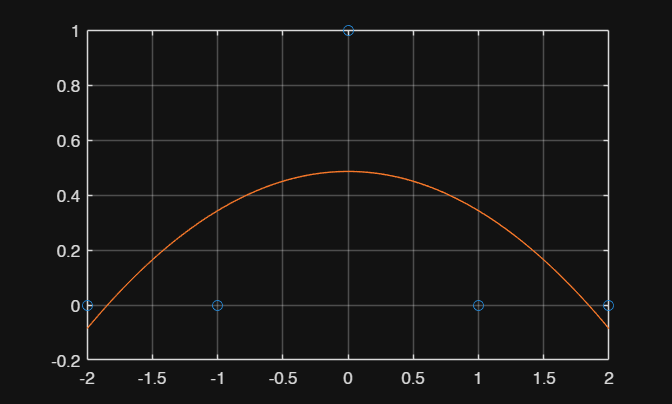

xx = linspace(-2,2,100);
yy = polyval(quad,xx);

plot(x,y,'o',xx,yy,'-')
grid on

x=[-2;-1;0;1;2];
y=[0;0;1;0;0];
quad1=polyfit(x,y,2);
disp("y= "+quad1(1)+"x^2 "+quad1(2)+"x "+quad1(3));

y= -0.14286x^2 1.7053e-17x 0.48571


quad2=[x.^2 x ones(size(x))];
z=quad2;
val=inv(z'*z)*z'*y;
disp("y= "+val(1)+"x^2 "+val(2)+"x "+val(3))

y= -0.14286x^2 0x 0.48571


l=[5;6;7];
F=[1;2;4];
quad=[F ones(size(F))];
v=inv(quad'*quad)*quad'*l

v =     0.6429
    4.5000


a=v(2);
disp("normal length a = "+a);

normal length a = 4.5


disp("proportionality constant b = "+v(1));

proportionality constant b = 0.64286


b=[4;3;1;0];
t=[-2;-1;0;2];
Aval=[1;1;1;1];
A=[Aval t]

A =      1    -2
     1    -1
     1     0
     1     2


fit=inv(A'*A)*A'*b;
disp("best straight line is a= "+fit(1)+" b= "+fit(2));

best straight line is a= 1.7429 b= -1.0286


if rank(A)==size(A,2)
    disp("Independent");
    p=A*inv(A'*A)*A'*b;
    disp(p);
else
    disp("dependent");
    p=A*inv(A)*b;
    disp(p);
end

Independent


    3.8000
    2.7714
    1.7429
   -0.3143



x=[-3;-2;-1;0;1;2;3];
y=[4;2;0;0;-2;-2;-3];
A=[x ones(size(x))];
fit=inv(A'*A)*A'*y;
disp("Straight line is: "+fit(1)+"x "+fit(2));

Straight line is: -1.1071x -0.14286


[B,text]=xlsread('Excel\excelsheet_1.xlsx');
x=B(:,1);
y=B(:,2);
n=length(x);
ATA=[sum(x.^2) sum(x); sum(x) n];
ATb=[sum(x.*y);sum(y)];
mandc=inv(ATA)*ATb;
disp(mandc(1)+"x "+mandc(2))

4.7729x -0.10261


[B,text]=xlsread("Excel\excelsheet_1.xlsx");
x=B(:,1);
y=B(:,2);
A=[x ones(size(x))];
n=length(x);
ATA=[sum(x.^2) sum(x); sum(x) n];
ATb=[sum(x.*y);sum(y)];
m_and_c=inv(ATA)*ATb;
disp("y= "+m_and_c(1)+"x "+m_and_c(2));

y= 4.7729x -0.10261


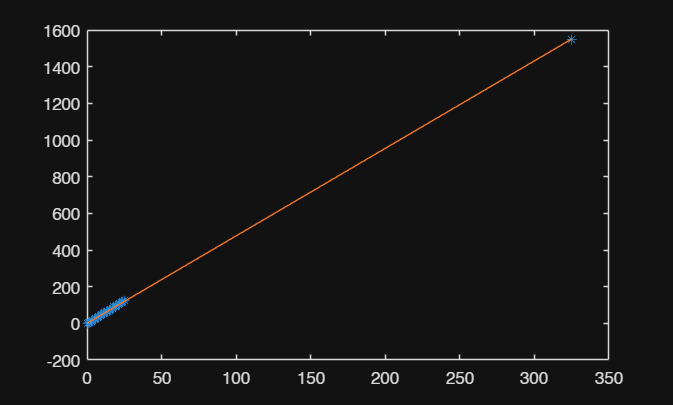

y_projected=A*m_and_c;
plot(x,y,'*')
hold on
plot(x,y_projected)

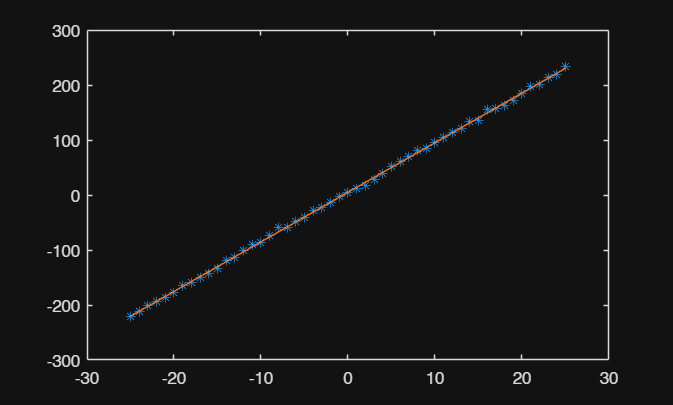

clear
clc
close
m=9;
c=5;
x=-25:1:25;
y=m*x+c;
n=length(x);
std=3;
noise=std*randn(1,n);
yn=y+noise;
plot(x,yn,'*')
hold on
A=[x' ones(size(x'))];
yn=yn';
mandc=pinv(A)*yn;
y_proj=A*pinv(A)*yn;
plot(x,y_proj);

mandc

mandc =     9.0164
    4.9512


A=[1 2 3; 4 5 6; 7 8 9];
[L,U]=lu(A)

L =     0.1429    1.0000         0
    0.5714    0.5000    1.0000
    1.0000         0         0


U =     7.0000    8.0000    9.0000
         0    0.8571    1.7143
         0         0    0.0000


AA=L*U

AA =      1     2     3
     4     5     6
     7     8     9


[Q,R]=qr(A,0)

Q =    -0.1231    0.9045    0.4082
   -0.4924    0.3015   -0.8165
   -0.8616   -0.3015    0.4082


R =    -8.1240   -9.6011  -11.0782
         0    0.9045    1.8091
         0         0   -0.0000


eig(A)

ans =    16.1168
   -1.1168
   -0.0000


B=A;
for i=1:10
    [Q,R]=qr(B,0);
    B=R*Q;
end
disp(B)

   16.1168   -4.8990   -0.0000
    0.0000   -1.1168    0.0000
    0.0000   -0.0000   -0.0000



diag(B)

ans =    16.1168
   -1.1168
   -0.0000


if norm(diag(B)-eig(A))<1e-10
    disp("Yes")
else
    disp("No")
end

Yes


A=randi([0,9],15,15);
Asm=(A+A')/2;
B=Asm;
for i=1:1000
    [Q,R]=qr(B,0);
    B=R*Q;
end
diag(B)

ans =    68.2099
   14.8838
  -13.4210
  -11.9067
   10.2399
   -8.1141
    7.4447
   -5.8266
    5.4955
    4.2745
   -3.9129
   -2.5178
    2.4262
    1.8864
   -1.1617


if norm(sort(diag(B))-sort(eig(Asm)))<1e-10
    disp("Eigen values are correct")
else
    disp("eigenvalues not correct")
end

Eigen values are correct


A=randi([0,9],7,6)*randi([0,9],6,9)

A =     78    53   106   127    56    98    51    84   143
   108    89   187   197    90   140   124   144   228
   152    70   185   169   131   137   117   136   184
    78    51   102   132    53    94    49    82   144
   109    23   123   119    93    53    74    76   104
   135    84   193   172   111   171    69   128   205
    70    47    79    96    45    92    32    60   105


rank(A)

ans = 6

[U,Z,V]=svd(A)

U =    -0.3008   -0.2652    0.0331    0.3175   -0.0753    0.3957    0.7583
   -0.4885   -0.2287    0.7123   -0.3124    0.1687   -0.2747   -0.0140
   -0.4691    0.4715   -0.0895   -0.3813   -0.5510    0.3087   -0.0734
   -0.2981   -0.2834    0.0845    0.5384   -0.0967    0.3456   -0.6364
   -0.2862    0.6925    0.0765    0.5099    0.3152   -0.2593    0.0784
   -0.4744   -0.1774   -0.6180   -0.2513    0.5416    0.0108   -0.0698
   -0.2346   -0.2525   -0.2977    0.2079   -0.5101   -0.6971    0.0576


Z =   930.8485         0         0         0         0         0         0         0         0
         0   89.8719         0         0         0         0         0         0         0
         0         0   60.0026         0         0         0         0         0         0
         0         0         0   35.0840         0         0         0         0         0
         0         0         0         0   19.7769         0         0         0         0
         0         0         0         0         0    6.3833         0         0         0
         0         0         0         0         0         0    0.0000         0         0


V =    -0.3034    0.4233   -0.3904    0.3212   -0.3627   -0.0827   -0.5769   -0.0423    0.0148
   -0.1772   -0.2970   -0.0158   -0.2799   -0.1873   -0.3230   -0.0995   -0.3424   -0.7316
   -0.4144    0.2052   -0.0768   -0.2779    0.7474   -0.3048   -0.1707    0.1483    0.0221
   -0.4203   -0.0979    0.2465    0.6504   -0.0256   -0.3126    0.3830    0.2557   -0.1398
   -0.2448    0.4970   -0.2693   -0.0818    0.0073    0.2986    0.6058   -0.3678   -0.1493
   -0.3309   -0.4107   -0.5060   -0.3155   -0.3002   -0.1457    0.2423    0.2263    0.3808
   -0.2222    0.3374    0.6196   -0.3915   -0.3918   -0.2477    0.0203   -0.0540    0.2853
   -0.3012    0.0051    0.1494   -0.1985   -0.1120    0.6036   -0.1170    0.5788   -0.3491
   -0.4676   -0.3891    0.2142    0.1393    0.1339    0.4027   -0.2039   -0.5188    0.2717


r=rank(A)

r = 6

CS=U(:,1:r)

CS =    -0.3008   -0.2652    0.0331    0.3175   -0.0753    0.3957
   -0.4885   -0.2287    0.7123   -0.3124    0.1687   -0.2747
   -0.4691    0.4715   -0.0895   -0.3813   -0.5510    0.3087
   -0.2981   -0.2834    0.0845    0.5384   -0.0967    0.3456
   -0.2862    0.6925    0.0765    0.5099    0.3152   -0.2593
   -0.4744   -0.1774   -0.6180   -0.2513    0.5416    0.0108
   -0.2346   -0.2525   -0.2977    0.2079   -0.5101   -0.6971


RS=V(:,1:r)

RS =    -0.3034    0.4233   -0.3904    0.3212   -0.3627   -0.0827
   -0.1772   -0.2970   -0.0158   -0.2799   -0.1873   -0.3230
   -0.4144    0.2052   -0.0768   -0.2779    0.7474   -0.3048
   -0.4203   -0.0979    0.2465    0.6504   -0.0256   -0.3126
   -0.2448    0.4970   -0.2693   -0.0818    0.0073    0.2986
   -0.3309   -0.4107   -0.5060   -0.3155   -0.3002   -0.1457
   -0.2222    0.3374    0.6196   -0.3915   -0.3918   -0.2477
   -0.3012    0.0051    0.1494   -0.1985   -0.1120    0.6036
   -0.4676   -0.3891    0.2142    0.1393    0.1339    0.4027


NS=V(:,r+1:end)

NS =    -0.5769   -0.0423    0.0148
   -0.0995   -0.3424   -0.7316
   -0.1707    0.1483    0.0221
    0.3830    0.2557   -0.1398
    0.6058   -0.3678   -0.1493
    0.2423    0.2263    0.3808
    0.0203   -0.0540    0.2853
   -0.1170    0.5788   -0.3491
   -0.2039   -0.5188    0.2717


LNS=U(:,r+1:end)

LNS =     0.7583
   -0.0140
   -0.0734
   -0.6364
    0.0784
   -0.0698
    0.0576


RS=orth(A')

RS =    -0.3034    0.4233   -0.3904    0.3212   -0.3627   -0.0827
   -0.1772   -0.2970   -0.0158   -0.2799   -0.1873   -0.3230
   -0.4144    0.2052   -0.0768   -0.2779    0.7474   -0.3048
   -0.4203   -0.0979    0.2465    0.6504   -0.0256   -0.3126
   -0.2448    0.4970   -0.2693   -0.0818    0.0073    0.2986
   -0.3309   -0.4107   -0.5060   -0.3155   -0.3002   -0.1457
   -0.2222    0.3374    0.6196   -0.3915   -0.3918   -0.2477
   -0.3012    0.0051    0.1494   -0.1985   -0.1120    0.6036
   -0.4676   -0.3891    0.2142    0.1393    0.1339    0.4027


CS=orth(A)

CS =    -0.3008   -0.2652    0.0331    0.3175   -0.0753    0.3957
   -0.4885   -0.2287    0.7123   -0.3124    0.1687   -0.2747
   -0.4691    0.4715   -0.0895   -0.3813   -0.5510    0.3087
   -0.2981   -0.2834    0.0845    0.5384   -0.0967    0.3456
   -0.2862    0.6925    0.0765    0.5099    0.3152   -0.2593
   -0.4744   -0.1774   -0.6180   -0.2513    0.5416    0.0108
   -0.2346   -0.2525   -0.2977    0.2079   -0.5101   -0.6971


NS=null(A)

NS =    -0.5769   -0.0423    0.0148
   -0.0995   -0.3424   -0.7316
   -0.1707    0.1483    0.0221
    0.3830    0.2557   -0.1398
    0.6058   -0.3678   -0.1493
    0.2423    0.2263    0.3808
    0.0203   -0.0540    0.2853
   -0.1170    0.5788   -0.3491
   -0.2039   -0.5188    0.2717


LNS=null(A')

LNS =     0.7583
   -0.0140
   -0.0734
   -0.6364
    0.0784
   -0.0698
    0.0576


RS'*NS

ans = 1.0e-15 *

    0.0884   -0.0160   -0.0190
   -0.0358   -0.0954    0.0285
    0.1735   -0.0546   -0.1009
    0.0201    0.1255   -0.0264
    0.1205    0.0110    0.1409
    0.2156   -0.1143   -0.0298


CS'*LNS

ans = 1.0e-15 *

    0.0139
   -0.0243
   -0.0659
   -0.4302
    0.0694
    0.0139


singval=diag(Z)

singval =   930.8485
   89.8719
   60.0026
   35.0840
   19.7769
    6.3833
    0.0000


sum=norm(A,'fro')^2

sum = 8.7982e+05

A=randi([0,9],9,9)

A =      5     9     0     3     1     7     8     2     0
     2     5     6     2     6     7     8     3     6
     2     3     2     5     2     5     9     3     3
     0     7     6     3     6     2     4     7     7
     6     4     2     1     3     3     8     0     1
     9     5     8     1     4     6     4     7     7
     1     3     3     7     7     8     0     6     0
     6     2     7     2     3     0     9     6     4
     7     7     2     8     3     7     5     8     8


[U,Z,V]=svd(A)

U =    -0.3008    0.4380   -0.5038    0.0883   -0.0002   -0.3487    0.4047    0.3795   -0.1632
   -0.3671    0.0301    0.0639   -0.4940   -0.1982   -0.2809   -0.5374   -0.0078   -0.4573
   -0.2831    0.2200   -0.1834   -0.2897    0.2668    0.3912   -0.3382    0.3090    0.5655
   -0.3329   -0.3561    0.2545   -0.3694    0.3886   -0.3922    0.4148   -0.1173    0.2654
   -0.2359    0.4766   -0.0326   -0.0378   -0.2683    0.0211    0.1030   -0.7538    0.2520
   -0.4067   -0.1013    0.3715    0.4863   -0.4430   -0.2210   -0.1419    0.2673    0.3364
   -0.2647   -0.5579   -0.4521   -0.1467   -0.4585    0.3616    0.2231   -0.0438   -0.0138
   -0.3180    0.2221    0.5079   -0.0498    0.0311    0.5508    0.3516    0.1482   -0.3729
   -0.4377   -0.1845   -0.2055    0.5156    0.5091    0.0956   -0.2382   -0.2884   -0.2410


Z =    41.7047         0         0         0         0         0         0         0         0
         0   12.5320         0         0         0         0         0         0         0
         0         0   11.8640         0         0         0         0         0         0
         0         0         0    8.3242         0         0         0         0         0
         0         0         0         0    6.8146         0         0         0         0
         0         0         0         0         0    6.3198         0         0         0
         0         0         0         0         0         0    4.5506         0         0
         0         0         0         0         0         0         0    2.5558         0
         0         0         0         0         0         0         0         0    0.0732


V =    -0.3145    0.3288    0.1304    0.7432   -0.3182    0.1504    0.0613   -0.3090    0.0221
   -0.3643    0.0908   -0.2558    0.0263    0.2187   -0.6772    0.4949   -0.0194    0.2028
   -0.2970   -0.1486    0.5259   -0.2046   -0.3733    0.0236    0.0688    0.3240    0.5672
   -0.2562   -0.2518   -0.4207    0.0200    0.3400    0.5331    0.0030   -0.1907    0.5073
   -0.2763   -0.3069    0.0144   -0.4169   -0.3653    0.0070    0.1399   -0.6542   -0.2728
   -0.3617   -0.1012   -0.5404    0.0254   -0.4174   -0.1482   -0.4868    0.3468   -0.1133
   -0.4265    0.7009    0.0520   -0.4276    0.1871    0.2588   -0.0474    0.0850   -0.1727
   -0.3531   -0.4043    0.1439    0.1908    0.1957    0.2500    0.3595    0.4039   -0.5114
   -0.3174   -0.1973    0.3852    0.1048    0.4636   -0.2872   -0.5988   -0.2103   -0.0274


CS=U(:,1:r)

CS =    -0.3008    0.4380   -0.5038    0.0883   -0.0002   -0.3487
   -0.3671    0.0301    0.0639   -0.4940   -0.1982   -0.2809
   -0.2831    0.2200   -0.1834   -0.2897    0.2668    0.3912
   -0.3329   -0.3561    0.2545   -0.3694    0.3886   -0.3922
   -0.2359    0.4766   -0.0326   -0.0378   -0.2683    0.0211
   -0.4067   -0.1013    0.3715    0.4863   -0.4430   -0.2210
   -0.2647   -0.5579   -0.4521   -0.1467   -0.4585    0.3616
   -0.3180    0.2221    0.5079   -0.0498    0.0311    0.5508
   -0.4377   -0.1845   -0.2055    0.5156    0.5091    0.0956


RS=V(:,1:r)

RS =    -0.3145    0.3288    0.1304    0.7432   -0.3182    0.1504
   -0.3643    0.0908   -0.2558    0.0263    0.2187   -0.6772
   -0.2970   -0.1486    0.5259   -0.2046   -0.3733    0.0236
   -0.2562   -0.2518   -0.4207    0.0200    0.3400    0.5331
   -0.2763   -0.3069    0.0144   -0.4169   -0.3653    0.0070
   -0.3617   -0.1012   -0.5404    0.0254   -0.4174   -0.1482
   -0.4265    0.7009    0.0520   -0.4276    0.1871    0.2588
   -0.3531   -0.4043    0.1439    0.1908    0.1957    0.2500
   -0.3174   -0.1973    0.3852    0.1048    0.4636   -0.2872


NS=V(:,r+1:end)

NS =     0.0613   -0.3090    0.0221
    0.4949   -0.0194    0.2028
    0.0688    0.3240    0.5672
    0.0030   -0.1907    0.5073
    0.1399   -0.6542   -0.2728
   -0.4868    0.3468   -0.1133
   -0.0474    0.0850   -0.1727
    0.3595    0.4039   -0.5114
   -0.5988   -0.2103   -0.0274


LNS=U(:,r+1:end)

LNS =     0.4047    0.3795   -0.1632
   -0.5374   -0.0078   -0.4573
   -0.3382    0.3090    0.5655
    0.4148   -0.1173    0.2654
    0.1030   -0.7538    0.2520
   -0.1419    0.2673    0.3364
    0.2231   -0.0438   -0.0138
    0.3516    0.1482   -0.3729
   -0.2382   -0.2884   -0.2410


RS'*NS

ans = 1.0e-15 *

   -0.2033   -0.0453   -0.0803
   -0.0514    0.8744    0.2547
   -0.0886    0.1830    0.1008
   -0.0423   -0.3487   -0.0558
   -0.1592    0.0017    0.2341
    0.0789   -0.4261    0.0928


CS'*LNS

ans = 1.0e-15 *

   -0.0253   -0.0424   -0.1183
    0.0982    0.2207    0.0746
   -0.2076    0.0009    0.0174
   -0.1897   -0.3424   -0.2041
    0.0289   -0.2560   -0.3036
    0.4941    0.1596    0.2730


v=diag(Z)

v =    41.7047
   12.5320
   11.8640
    8.3242
    6.8146
    6.3198
    4.5506
    2.5558
    0.0732


z=norm(v,'fro')^2

z = 2.2200e+03

q=U*V';
s=V*Z*V';
q*s

ans =     5.0000    9.0000    0.0000    3.0000    1.0000    7.0000    8.0000    2.0000    0.0000
    2.0000    5.0000    6.0000    2.0000    6.0000    7.0000    8.0000    3.0000    6.0000
    2.0000    3.0000    2.0000    5.0000    2.0000    5.0000    9.0000    3.0000    3.0000
    0.0000    7.0000    6.0000    3.0000    6.0000    2.0000    4.0000    7.0000    7.0000
    6.0000    4.0000    2.0000    1.0000    3.0000    3.0000    8.0000    0.0000    1.0000
    9.0000    5.0000    8.0000    1.0000    4.0000    6.0000    4.0000    7.0000    7.0000
    1.0000    3.0000    3.0000    7.0000    7.0000    8.0000    0.0000    6.0000    0.0000
    6.0000    2.0000    7.0000    2.0000    3.0000    0.0000    9.0000    6.0000    4.0000
    7.0000    7.0000    2.0000    8.0000    3.0000    7.0000    5.0000    8.0000    8.0000


pinv(A)

ans =    -0.0818   -0.1814    0.1054    0.0353    0.1920    0.1305    0.0034   -0.1046   -0.0202
   -0.3570   -1.3017    1.5021    0.8300    0.7107    0.9209   -0.0596   -1.0614   -0.6772
   -1.2398   -3.5264    4.4023    2.0531    1.8697    2.6715   -0.0907   -2.8428   -1.9524
   -1.1780   -3.2052    3.9464    1.8349    1.7848    2.2641   -0.0562   -2.5689   -1.6013
    0.5098    1.7272   -2.2010   -0.9385   -0.7374   -1.3224    0.1168    1.3621    0.9194
    0.2913    0.7814   -0.8145   -0.4927   -0.4879   -0.4480    0.0381    0.5226    0.3422
    0.4001    1.0984   -1.2678   -0.6363   -0.5964   -0.8295    0.0081    0.9251    0.5463
    1.2032    3.1267   -3.9201   -1.8363   -1.8937   -2.3192    0.1197    2.6807    1.6574
   -0.0274    0.2399   -0.2030   -0.0882   -0.0723   -0.1264   -0.0739    0.0729    0.1816


s=A*A'

s =    233   186   167   138   157   185   128   141   230
   186   263   187   222   155   254   165   200   256
   167   187   170   148   129   170   124   159   213
   138   222   148   248   106   236   160   186   249
   157   155   129   106   140   160    76   145   160
   185   254   170   236   160   337   173   240   308
   128   165   124   160    76   173   217   104   215
   141   200   159   186   145   240   104   235   220
   230   256   213   249   160   308   215   220   377


ev=eig(A*A')

ev = 1.0e+03 *

    0.0000
    0.0065
    0.0207
    0.0399
    0.0464
    0.0693
    0.1408
    0.1571
    1.7393


sort(sqrt(abs(ev)),'descend')

ans =    41.7047
   12.5320
   11.8640
    8.3242
    6.8146
    6.3198
    4.5506
    2.5558
    0.0732


A=[9 3; 4 5];
[U,Z,V]=svd(A);
Q=U*V';
S=V*Z*V';
check=(Q*S)

check =     9.0000    3.0000
    4.0000    5.0000


ocheck=Q*Q'

ocheck =     1.0000         0
         0    1.0000


S-S' %its symmetric

ans =      0     0
     0     0


close all
[x,y]=meshgrid(-5:0.5:5);
f=S(1,1)*x.^2+2*S(1,2)*x.*y+S(2,2)*y.^2

f =   518.3223  457.5842  401.4771  350.0011  303.1562  260.9423  223.3595  190.4077  162.0870  138.3974  119.3388  104.9113   95.1148   89.9494   89.4150   93.5118  102.2395  115.5983  133.5882  156.2092  183.4612
  478.9049  419.8411  365.4083  315.6066  270.4360  229.8964  193.9879  162.7105  136.0641  114.0487   96.6644   83.9112   75.7890   72.2979   73.4379   79.2089   89.6110  104.6441  124.3083  148.6035  177.5298
  441.8742  384.4847  331.7263  283.5989  240.1026  201.2373  167.0031  137.3999  112.4278   92.0868   76.3768   65.2979   58.8501   57.0333   59.8475   67.2928   79.3692   96.0766  117.4151  143.3847  173.9853
  407.2303  351.5151  300.4310  253.9779  212.1559  174.9649  142.4050  114.4762   91.1784   72.5117   58.4760   49.0714   44.2979   44.1554   48.6439   57.7635   71.5142   89.8960  112.9088  140.5526  172.8275
  374.9732  320.9323  271.5225  226.7437  186.5960  151.0794  120.1938   93.9392   72.3158   55.3233   42.9620   35.2317   32.1324   33.6642   39.8271  

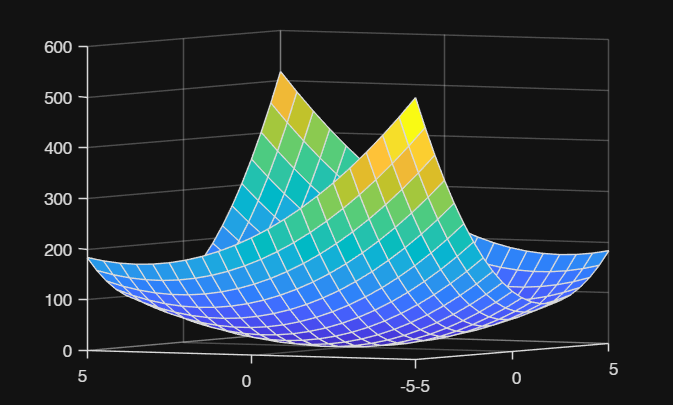

surf(x,y,f)

A=randi([0,9],50,50);
for i=1:50
    [Q,R]=qr(A,0);
    A=R*Q;
end
diag(A)

ans =   231.5023
   22.3744
  -14.2390
  -13.5121
    8.6737
    6.9545
   11.8644
    7.8435
   14.8454
   16.3789
   -0.1005
   -5.9896
  -13.9544
   -8.3650
   12.5440


A=[3 3; -1 1];
[U,Z,V]=svd(A);
Q=U*V';
S=V*Z*V';
A=Q*S

A =     3.0000    3.0000
   -1.0000    1.0000


A=randi([0,9],9,9);
rank(A)

ans = 9

[U,Z,V]=svd(A)

U =    -0.4143   -0.2514    0.0767   -0.3796   -0.4328    0.0036    0.1052   -0.2861   -0.5787
   -0.3330   -0.1443    0.3141    0.3415    0.5111   -0.5690   -0.0238   -0.1894   -0.1778
   -0.2805    0.2589    0.2112    0.2629   -0.3478   -0.0304   -0.6019    0.4851   -0.1454
   -0.2591    0.6247   -0.3320   -0.2853   -0.0063   -0.2910   -0.2184   -0.4107    0.2235
   -0.3691   -0.3742   -0.0649    0.2105    0.0690    0.4981   -0.3829   -0.3880    0.3538
   -0.3019   -0.1111    0.1627   -0.6718    0.4305    0.0832   -0.0892    0.4335    0.1747
   -0.3666   -0.2245   -0.0898    0.1072   -0.4131   -0.3467    0.3962    0.2257    0.5449
   -0.3165    0.0135   -0.7375    0.2248    0.2540    0.1362    0.1576    0.2958   -0.3312
   -0.3311    0.5058    0.3974    0.1763    0.0720    0.4437    0.4920   -0.0367    0.0109


Z =    45.4135         0         0         0         0         0         0         0         0
         0   13.1583         0         0         0         0         0         0         0
         0         0   10.8394         0         0         0         0         0         0
         0         0         0    9.3666         0         0         0         0         0
         0         0         0         0    8.3618         0         0         0         0
         0         0         0         0         0    6.6658         0         0         0
         0         0         0         0         0         0    3.0341         0         0
         0         0         0         0         0         0         0    2.0094         0
         0         0         0         0         0         0         0         0    0.8051


V =    -0.3259   -0.3942   -0.2940    0.5949    0.3286    0.0081   -0.1385    0.0571   -0.4092
   -0.2713    0.2911    0.6384   -0.0712    0.4757    0.1090   -0.1530    0.3856   -0.1368
   -0.3269   -0.2739   -0.1137   -0.6237    0.1589    0.2204    0.4498   -0.1514   -0.3422
   -0.2341    0.5193   -0.3827   -0.1816    0.0268    0.2555   -0.5510   -0.3288   -0.1357
   -0.3843    0.0651    0.1286    0.1934   -0.7226    0.4130    0.1008    0.2695   -0.1366
   -0.2962    0.5455   -0.0319    0.2724    0.0310   -0.4207    0.5436   -0.2465   -0.0725
   -0.3491   -0.0662   -0.1237    0.1318    0.2606    0.3739    0.1559   -0.0555    0.7785
   -0.4201   -0.0779   -0.2818   -0.2999   -0.1254   -0.5666   -0.2044    0.4791    0.2002
   -0.3532   -0.3208    0.4841   -0.0091   -0.1817   -0.2567   -0.2823   -0.5924    0.0913


Q=U*V';
S=V*Z*V';
eig(S)

ans =    45.4135
   13.1583
    0.8051
    2.0094
    3.0341
   10.8394
    9.3666
    8.3618
    6.6658


if all(eig(S)>0)
    disp("Positive definite")
else
    disp("Not")
end

Positive definite


A=Q*S;

A=randi([0,9],9,7)*randi([0,9],7,9);
rank(A)

ans = 7

[U,Z,V]=svd(A)

U =    -0.3427   -0.3648    0.4876   -0.3627    0.1402    0.0947   -0.2509   -0.5318   -0.0768
   -0.3207   -0.1907   -0.0105   -0.3895   -0.0573   -0.5215    0.0341    0.3934    0.5271
   -0.2698    0.1509   -0.0585   -0.2389   -0.5570   -0.2720    0.0146    0.0749   -0.6737
   -0.3348   -0.3123   -0.5534   -0.2715    0.2041    0.5317    0.1357    0.2137   -0.1483
   -0.3030    0.2562   -0.5452    0.1448    0.2954   -0.3970   -0.1490   -0.5062    0.0312
   -0.3145   -0.2233   -0.0258    0.5281   -0.2447    0.1025   -0.6663    0.2310    0.0631
   -0.1880    0.1325    0.2991    0.1336    0.6757   -0.1967   -0.0293    0.4281   -0.4006
   -0.3724    0.7490    0.1736   -0.1734   -0.0649    0.3940   -0.0889    0.0609    0.2628
   -0.4797   -0.1277    0.1871    0.4879   -0.1315    0.0176    0.6651   -0.1210    0.0768


Z = 1.0e+03 *

    1.2163         0         0         0         0         0         0         0         0
         0    0.0885         0         0         0         0         0         0         0
         0         0    0.0724         0         0         0         0         0         0
         0         0         0    0.0536         0         0         0         0         0
         0         0         0         0    0.0349         0         0         0         0
         0         0         0         0         0    0.0287         0         0         0
         0         0         0         0         0         0    0.0110         0         0
         0         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0         0    0.0000


V =    -0.4762    0.0939    0.2867    0.2671    0.1563   -0.5444   -0.4937   -0.1732   -0.1279
   -0.2922    0.0734   -0.4331    0.4034    0.5473    0.3704   -0.0027    0.2589   -0.2347
   -0.3685    0.0226   -0.3685   -0.4779    0.0948   -0.4936    0.4680    0.0869   -0.1427
   -0.3102    0.0305   -0.2032   -0.3554   -0.4357    0.3852   -0.3784   -0.1988   -0.4630
   -0.3545    0.4497    0.1587   -0.2405   -0.0873    0.1805   -0.1496    0.5074    0.5187
   -0.2596   -0.7745   -0.1367   -0.1598    0.1393    0.0930   -0.2157   -0.0683    0.4575
   -0.2901   -0.3830    0.5398    0.1391   -0.1998    0.1210    0.3446    0.4090   -0.3433
   -0.2812    0.0370   -0.3297    0.5490   -0.5842   -0.0598    0.2477   -0.1580    0.2796
   -0.3155    0.1850    0.3304   -0.0847    0.2625    0.3391    0.3809   -0.6336    0.1395


Q=U*V';
S=V*Z*V';
A=Q*S;

if all(eig(S)>0) ||  all(eig(S)==0)
    disp("Positive definite")
else
    disp("Not")
end

Not


A=randi([0,9],5,3)*randi([0,9],3,3);
rank(A)

ans = 3

[U,Z,V]=svd(A);
r=rank(A)

r = 3

LNS=null(A')

LNS =    -0.0991   -0.3884
   -0.3867   -0.2894
    0.8655    0.0642
    0.2387   -0.2029
   -0.1856    0.8486


NS=null(A)


NS =

  3×0 empty double matrix



A=randi([0,9],5,3)*randi([0,9],3,3);
[U,Z,V]=svd(A)

U =    -0.6006    0.1072   -0.5468   -0.4278   -0.3819
   -0.3605    0.4686    0.7346   -0.0184   -0.3324
   -0.3620    0.4984   -0.1480    0.1438    0.7603
   -0.4204   -0.2700   -0.1044    0.8360   -0.2016
   -0.4488   -0.6690    0.3587   -0.3117    0.3536


Z =   268.5747         0         0
         0   28.3378         0
         0         0   10.0791
         0         0         0
         0         0         0


V =    -0.2956    0.9497    0.1032
   -0.8336   -0.3092    0.4578
   -0.4667   -0.0493   -0.8830


rs=V(:,1:r)

rs =    -0.2956    0.9497    0.1032
   -0.8336   -0.3092    0.4578
   -0.4667   -0.0493   -0.8830


cs=U(:,1:r)

cs =    -0.6006    0.1072   -0.5468
   -0.3605    0.4686    0.7346
   -0.3620    0.4984   -0.1480
   -0.4204   -0.2700   -0.1044
   -0.4488   -0.6690    0.3587


ns=V(:,r+1:end)


ns =

  3×0 empty double matrix



lns=U(:,r+1:end)

lns =    -0.4278   -0.3819
   -0.0184   -0.3324
    0.1438    0.7603
    0.8360   -0.2016
   -0.3117    0.3536


A=[9 -2 3;
    4 9 -5;
    6 -1 -1];
B=[1;3;3];
[L,U]=lu(A)

L =     1.0000         0         0
    0.4444    1.0000         0
    0.6667    0.0337    1.0000


U =     9.0000   -2.0000    3.0000
         0    9.8889   -6.3333
         0         0   -2.7865


Y=L\B

Y =     1.0000
    2.5556
    2.2472


X=U\Y

X =     0.3226
   -0.2581
   -0.8065


Pss=pinv(A);
[U,Z,V]=svd(A)

U =    -0.5865    0.6375   -0.4996
   -0.6756   -0.7252   -0.1324
   -0.4467    0.2599    0.8561


Z =    11.7400         0         0
         0   10.5922         0
         0         0    1.9943


V =    -0.9081    0.4151    0.0555
   -0.3800   -0.7611   -0.5256
    0.1759    0.4984   -0.8489


nigga=V*pinv(Z)*U'

nigga =     0.0565    0.0202    0.0685
    0.1048    0.1089   -0.2298
    0.2339    0.0121   -0.3589


norm(Pss-nigga)

ans = 1.3878e-17

A=pascal(7)

A =      1     1     1     1     1     1     1
     1     2     3     4     5     6     7
     1     3     6    10    15    21    28
     1     4    10    20    35    56    84
     1     5    15    35    70   126   210
     1     6    21    56   126   252   462
     1     7    28    84   210   462   924


[L,U]=lu(A)

L =     1.0000         0         0         0         0         0         0
    1.0000    0.1667    0.5556   -1.0000    1.0000         0         0
    1.0000    0.3333    0.8889   -0.8000    0.6000   -1.0000    1.0000
    1.0000    0.5000    1.0000         0         0         0         0
    1.0000    0.6667    0.8889    0.8000   -0.2000    1.0000         0
    1.0000    0.8333    0.5556    1.0000         0         0         0
    1.0000    1.0000         0         0         0         0         0


U =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    6.0000   27.0000   83.0000  209.0000  461.0000  923.0000
         0         0   -4.5000  -22.5000  -70.5000 -175.5000 -378.5000
         0         0         0   -1.6667  -10.0000  -35.6667  -97.8889
         0         0         0         0   -1.6667  -10.0000  -35.4444
         0         0         0         0         0    0.2000    1.3333
         0         0         0         0         0         0    0.0667


[pmat,L,U]=lu(A)

pmat =     1.0000         0         0         0         0         0         0
    1.0000    1.0000         0         0         0         0         0
    1.0000    0.5000    1.0000         0         0         0         0
    1.0000    0.8333    0.5556    1.0000         0         0         0
    1.0000    0.1667    0.5556   -1.0000    1.0000         0         0
    1.0000    0.6667    0.8889    0.8000   -0.2000    1.0000         0
    1.0000    0.3333    0.8889   -0.8000    0.6000   -1.0000    1.0000


L =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    6.0000   27.0000   83.0000  209.0000  461.0000  923.0000
         0         0   -4.5000  -22.5000  -70.5000 -175.5000 -378.5000
         0         0         0   -1.6667  -10.0000  -35.6667  -97.8889
         0         0         0         0   -1.6667  -10.0000  -35.4444
         0         0         0         0         0    0.2000    1.3333
         0         0         0         0         0         0    0.0667


U =      1     0     0     0     0     0     0
     0     0     0     0     0     0     1
     0     0     0     1     0     0     0
     0     0     0     0     0     1     0
     0     1     0     0     0     0     0
     0     0     0     0     1     0     0
     0     0     1     0     0     0     0


norm(A-L*U)

ans = 1.2909e+03

U=A;
n=size(A,1)
L=eye(n)
for i=1:n-1
    for j=i+1:n
        m=U(i,k)\U(k,k)
        U=
        L=